# Uniform shear model with stability correction (Chougule et al, 2018)

The following example illustrates the uniform shear model with stability correction by Chougule et al. [1]  of . Note that this is a personnal numerical implementation that likely differs from the one used by Chougule et al. [1]. In particular, I did use a more intuitive approach. In this example, Figure 1 in Chougule et al. [1]  is reproduced.

References:

[1] Chougule, A., Mann, J., Kelly, M.,  & Larsen, G. C. (2018). Simplification and validation of a  spectral-tensor model for turbulence including atmospheric stability. *Boundary-Layer Meteorology*, *167*(3), 371-397.

## Initialisation and call of the main function

% Basic parameters definitions
clearvars;close all;clc;
zeta = [0.15,-0.03,0]; % Non dimensional Obukhov length
GAMMA = 3.2; % Shear parameter
L = 10; % m
alphaEps =0.05; % m^(4/3)/s^2

% frequency steps
N1 = 30; % number of frequency steps
FM = zeros(N1,4,4,numel(zeta)); % preallocation
myIter = [15,30,15]; % Number of iteration for each stability class for the umerical solution of the RDT equations
for ii=1:numel(zeta)
    tic
    [PHI,k11,k2_log,k3_log] = ChouguleTurb(alphaEps,GAMMA,L,zeta(ii),'N1',N1,'Niter',myIter(ii));
    FM0= squeeze(trapz(k3_log,trapz(k2_log,PHI,2),3));
    FM(:,:,:,ii) = FM0(end-N1+1:end,:,:);
    toc
end

Elapsed time is 79.467781 seconds.
Elapsed time is 177.812289 seconds.
Elapsed time is 106.859252 seconds.


## Visualization of the power spectral densities

Power spectral densities (PSD) associated with the unstable conditions are shown as dashed lines. Those corresponding to stable conditions are visualized with solid lines. FInally, the PSDs associated with neutral conditions are shown as dotted curves.

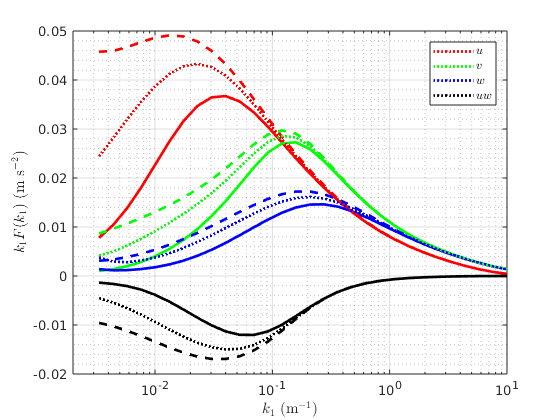

clf;close all
figure

myStyleU = {'r-','r--','r:'};
myStyleV = {'g-','g--','g:'};
myStyleW = {'b-','b--','b:'};
myStyleUW = {'k-','k--','k:'};
clear p
for ii=1:numel(zeta)
    p(1) = semilogx(k11,k11.*(FM(:,1,1,ii)'),myStyleU{ii},'linewidth',2);
    hold on
    p(2) = semilogx(k11,k11.*(FM(:,2,2,ii)'),myStyleV{ii},'linewidth',2);
    p(3) = semilogx(k11,k11.*(FM(:,3,3,ii)'),myStyleW{ii},'linewidth',2);
    p(4) = semilogx(k11,k11.*(FM(:,1,3,ii)'),myStyleUW{ii},'linewidth',2);
end
leg=legend(p,'$u$','$v$','$w$','$uw$');
set(leg,'interpreter','latex')
set(gca,'yscale','lin')
hold on
xlabel('$k_1$ (m$^{-1}$)','interpreter','latex')
ylabel('$k_1 F(k_1) $ (m s$^{-2}$)','interpreter','latex')
axis tight
set(gcf,'color','w')
ylim([-0.02,0.05])
xlim([2e-3,10])
set(leg,'interpreter','latex')
grid on
grid minor

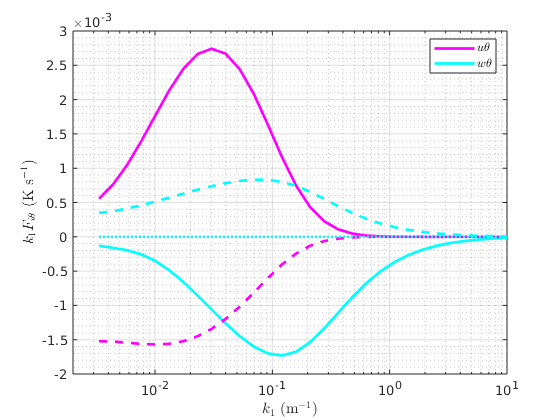


clear p
figure
myStyleUT = {'m-','m--','m:'};
myStyleWT = {'c-','c--','c:'};
for ii=1:numel(zeta)
    p(1) = semilogx(k11,k11.*(FM(:,1,4,ii)'),myStyleUT{ii},'linewidth',2);
    hold on
    p(2) = semilogx(k11,k11.*(FM(:,3,4,ii)'),myStyleWT{ii},'linewidth',2);
end
leg=legend(p,'$u \theta$','$w \theta$');
set(leg,'interpreter','latex')
hold on
xlabel('$k_1$ (m$^{-1}$)','interpreter','latex')
ylabel('$k_1 F_{i \theta} $ (K s$^{-1}$)','interpreter','latex')
axis tight
set(gcf,'color','w')
leg=legend('$u \theta$','$w \theta$','location','best');
set(leg,'interpreter','latex')
grid on
grid minor
xlim([2e-3,10])
ylim([-0.002,0.003])

## Some comments about the model

The uniform shear model implemented in [https://www.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994](https://www.mathworks.com/matlabcentral/fileexchange/67055-uniform-shear-model-mann-1994) relied on an analytical solution of the rapid-distortion theory equations. In the present case, numerical solutions are obtained using the 4th order Runge-Kutta method. This means that the accuracy of the numerical solution is affected by the number of iterations, given by the variable "Niter". For near-neutral and stable conditions, the number of iterations can be fairly low, around 15-20. In the case of a slightly unstable flow, the number of iterations has to be increased to provide a solution that converges. Divergence issues arise as soon as a slightly unstable atmosphere is modelled, i.e. a non-dimensional Obukhov length around -0.1 or lower. That is probably the reason why Chougule et al. [1] do not include the low-frequency content of their computed power spectral density in e.g. Fig 5. This issue limits the applicability of the model by Chougule et al if the atmospheric stratification is unstable.